%im = imread('cameraman.tif')
%im = imread("IR_0100.png")
im = imread('masked.png')

im = 240×320 uint8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   207   206   206   204   206   200   203   201   199   199   193   196   197   199   198   201   199   198   199   201   204   205   204   206   206   206   204   203   199
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   205   206   207   208   204   201   202   205   200   196   195   196   197   200   201   201   196   197   196   198   202   204   204   208   204   205   202   202   201
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   206   205   208   206   202   204   201   200   196   197   195   200   200   199   198   198   194   196   198   203   204   205   206   205   205   201   201   200
     0     0     0     0     0     0     0     0     0     0     0     


%im = im2gray(im)
im=mat2gray(im)

im =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8118    0.8078    0.8078    0.8000    0.8078    0.7843    0.7961    0.7882    0.7804    0.7804    0.7569    0.7686    0.7725    0.7804    0.7765    0.7882    0.7804    0.7765    0.7804    0.7882    0.8000    0.8039    0.8000    0.8078    0.8078    0.8078    0.8000    0.7961    0.7804
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.8039    0.8078    0.8118    0.8157    0.8000    0.7882    0.7922    0.8039    0.7843    0.7686    0.7647    0.7686    0.7725    0.7843    0.7882    0.7882    0.7686    0.7725    0.7686    0.7765    0.7922    0.8000    0.8000    0.8157    0.8000    0.8039    0.7922    0.7922    

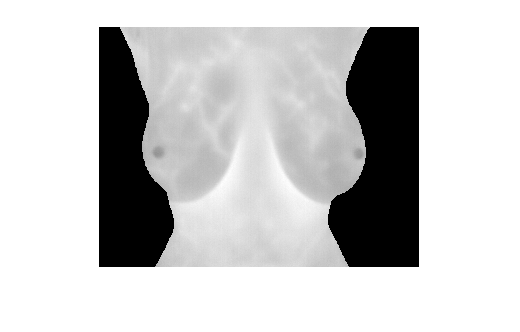

%im = rgb2gray(im);
imshow(im)

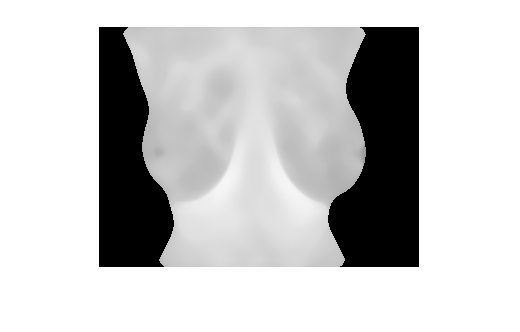


median_im = medfilt2(im,[15 15]);
imshow(median_im)


subtracted_im = median_im - im

subtracted_im =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.8118   -0.8078   -0.8078   -0.8000   -0.8078   -0.7843   -0.7961   -0.7882   -0.0157   -0.0157         0   -0.0157   -0.0235   -0.0314   -0.0275   -0.0392   -0.0314   -0.0275   -0.0314   -0.0392   -0.0510   -0.0549   -0.0510   -0.0588   -0.0588   -0.0471   -0.0235   -0.0157         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.8039   -0.8078   -0.8118   -0.8157   -0.8000   -0.7882   -0.7922   -0.0353   -0.0157         0    0.0039   -0.0039   -0.0078   -0.0196   -0.0235   -0.0235   -0.0039   -0.0078   -0.0039   -0.0118   -0.0275   -0.0353   -0.0353   -0.0510   -0.0275   -0.0235   -0.0078   

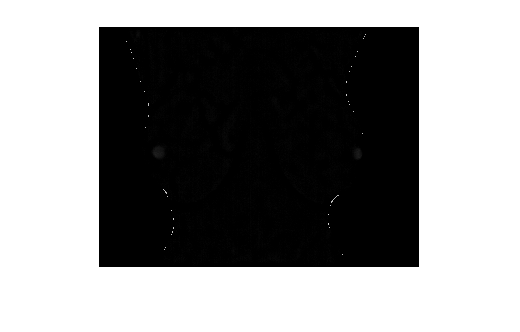

imshow(subtracted_im)


T = imbinarize(subtracted_im, 0.03)

T = 240×320 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

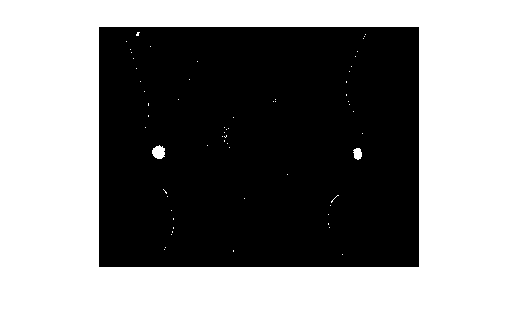

imshow(T)